t = readtable("10Ax1.tsv", "FileType","text",'Delimiter', '\t');


frame_num = 1

frame_num = 1


CLL = [t.CLLX(frame_num), t.CLLY(frame_num), t.CLLZ(frame_num)]; % Lateral femoral epicondyle
CML = [t.CMLX(frame_num), t.CMLY(frame_num), t.CMLZ(frame_num)]; % Medial femoral epicondyle
SIASL = [t.SIASLX(1), t.SIASLY(1), t.SIASLZ(1)]; % Left hip center

knee_midpoint = (CLL + CML) / 2

knee_midpoint = 1.0e+03 *

    1.3428    0.4355    0.9126


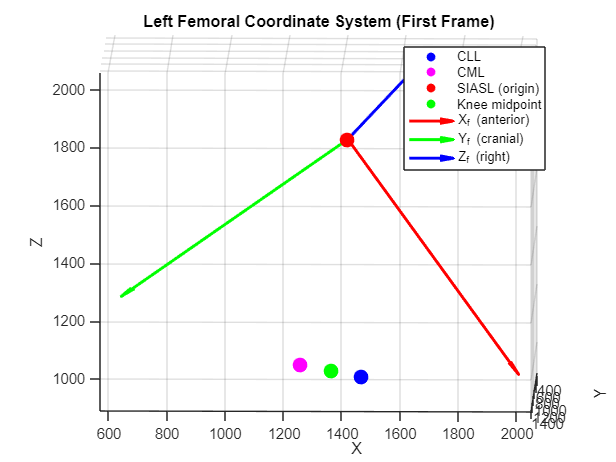


% Y-axis (cranial): from knee midpoint to SIASL
Y_femur = SIASL - knee_midpoint;
Y_femur = Y_femur / norm(Y_femur);

% Z-axis (right): perpendicular to Y, in plane of origin and FEs
v1 = CLL - SIASL;
v2 = CML - SIASL;
plane_normal = cross(v1, v2);  % Normal vector of the plane
Z_femur = cross(Y_femur, plane_normal);  % Ensure Z is perpendicular to Y
Z_femur = Z_femur / norm(Z_femur);

% X-axis (anterior)
X_femur = cross(Y_femur, Z_femur);
X_femur = X_femur / norm(X_femur);

% Build the attitude matrix
F_femur = [X_femur; Y_femur; Z_femur];  % Each row is an axis vector


% Visualization
figure;
hold on; grid on; axis equal;

% Scale factor for arrows
scale_factor = 1000;

% Plot key landmarks
scatter3(CLL(1), CLL(2), CLL(3), 100, 'b', 'filled'); % CLL
scatter3(CML(1), CML(2), CML(3), 100, 'm', 'filled'); % CML
scatter3(SIASL(1), SIASL(2), SIASL(3), 100, 'r', 'filled'); % SIASL (origin)
scatter3(knee_midpoint(1), knee_midpoint(2), knee_midpoint(3), 100, 'g', 'filled'); % Knee midppoint

% Draw axes from SIASL (origin)
quiver3(SIASL(1), SIASL(2), SIASL(3), X_f(1)*scale_factor, X_f(2)*scale_factor, X_f(3)*scale_factor, 0, 'r', 'LineWidth', 2); % X_f (anterior)
quiver3(SIASL(1), SIASL(2), SIASL(3), Y_f(1)*scale_factor, Y_f(2)*scale_factor, Y_f(3)*scale_factor, 0, 'g', 'LineWidth', 2); % Y_f (cranial)
quiver3(SIASL(1), SIASL(2), SIASL(3), Z_f(1)*scale_factor, Z_f(2)*scale_factor, Z_f(3)*scale_factor, 0, 'b', 'LineWidth', 2); % Z_f (right)

% Labels and view settings
legend('CLL', 'CML', 'SIASL (origin)','Knee midpoint ', 'X_f (anterior)', 'Y_f (cranial)', 'Z_f (right)');
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Left Femoral Coordinate System (First Frame)');
view(3); % 3D perspective view
hold off;